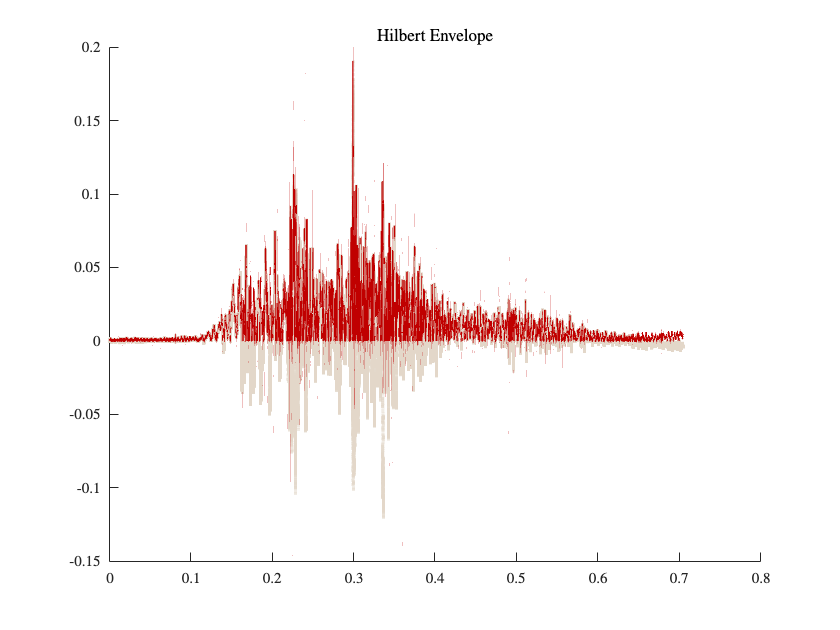

%% Cleanup and Setup
clear; clc; close all;
format short eng
% Plot Colors
LUCopper = [147, 86, 14]/255;
LUCopper_Light = [225, 213, 199]/255;
LUBlue = [17, 55, 125]/255;
LUBlue_Light = [197, 204, 221]/255;
Red_Dark = [192, 0, 0]/255;
Red_Light = [235, 200, 197]/255;
pink = [255, 199, 206]/255;

%% Step 1: Generate Sample Data (Replace with your data)
load('E2038.mat');   % Suppose data is in a variable pz
data = p(:,6);      % Adjust column to your data of interest
Fs = fs;             % Sampling frequency in Hz
t = (0:length(data)-1)'/Fs;
% Optional: Mean-subtraction to remove DC offset/baseline
data = data - mean(data(1:10));
y = data;
% Compute the upper and lower envelopes of the signal. 
% Choose a minimum peak separation (np) based on your data characteristics.
% [up,lo] = envelope(y);
% np = 3000;  
np = 2500;

[up, lo] = envelope(y, np, 'peak');

% Compute the upper and lower envelopes of the signal. 
% Use a Hilbert filter with a length of np. 
% Plot the channels and the envelopes. Use solid lines for the upper envelopes and dashed lines for the lower envelopes.
% [up, lo] = envelope(y, np, 'analytic');

% moving RMS envelopes 
% [up, lo] = envelope(y, np, 'rms');

y_env = hilbert(y);
env = abs(y)';

% Plot
figure
scatter(t, y, '.', ...
    'MarkerEdgeColor', LUCopper_Light, ...
    'MarkerEdgeAlpha', 0.2);   % <--- Transparency set here (20% opaque)

plot_param = {'Color', Red_Dark,'Linewidth',1}; 
hold on
plot(t,env,'Color', Red_Dark,'Linewidth',1)
% plot(t,-1*env,'Color', LUBlue,'Linewidth',1)
hold off
% xlim([0 0.04])
title('Hilbert Envelope')

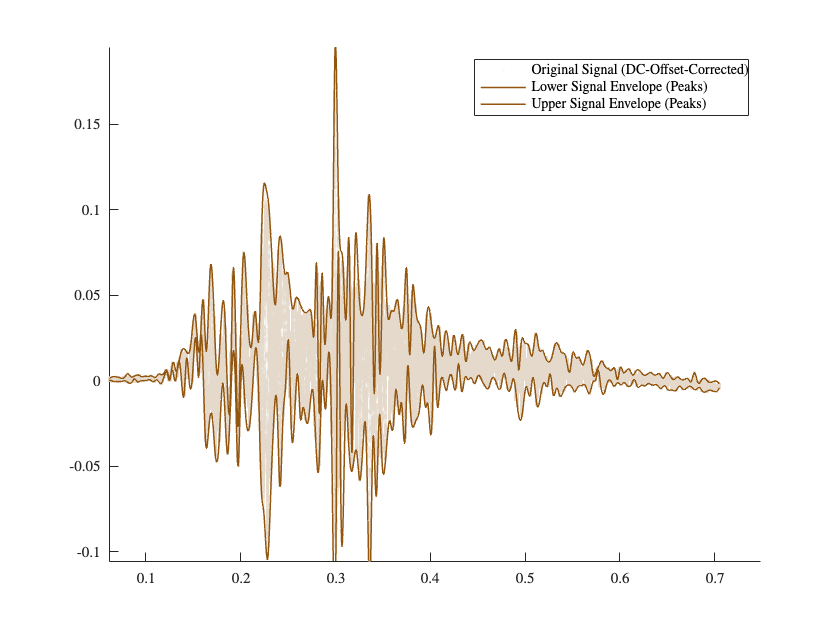

% Plot
figure
scatter(t, y, '.', ...
    'MarkerEdgeColor', LUCopper_Light, ...
    'MarkerEdgeAlpha', 0.1);   % <--- Transparency set here (20% opaque)
hold on
plot(t,lo,'-','Color', LUCopper,'Linewidth',1)
plot(t,up,'-','Color', LUCopper,'Linewidth',1)
% plot(t,up,'-','Color', Red_Dark,'Linewidth',1)
legend('Original Signal (DC-Offset-Corrected)','Lower Signal Envelope (Peaks)','Upper Signal Envelope (Peaks)')
hold off

% Separating Signal Components in Time
% Perform the MODWT and MRA
w = modwt(y,5);         % Compute the MODWT of y at 8 levels
mra = modwtmra(w);       % Obtain the multiresolution analysis

% Plot the original signal
figure;
subplot(5,1,1);
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal');

% Plot the reconstructed MRA components (e.g., detail levels 2,3,4)
subplot(5,1,2);
plot(t, mra(2,:), 'DisplayName','Level 2');
xlabel('Time (s)');
ylabel('Amplitude');
title('MRA Detail Components (Levels 2)');
legend;
subplot(5,1,3);
plot(t, mra(3,:), 'DisplayName','Level 3');
xlabel('Time (s)');
ylabel('Amplitude');
title('MRA Detail Components (Levels 3)');
legend;
subplot(5,1,4);
plot(t, mra(4,:), 'DisplayName','Level 4');
xlabel('Time (s)');
ylabel('Amplitude');
title('MRA Detail Components (Levels 4)');
legend;
subplot(5,1,5);
plot(t, mra(5,:), 'DisplayName','Level 5');
xlabel('Time (s)');
ylabel('Amplitude');
title('MRA Detail Components (Levels 5)');
legend;


% % Plot the approximation or another selected component (e.g., Level 9 if available)
% subplot(3,1,3);
% plot(t, mra(9,:), 'DisplayName','Level 9');
% xlabel('Time (s)');
% ylabel('Amplitude');
% title('MRA Approximation (Level 9)');
% legend;

% % % % % % % % % % % % % % % % 

%% Compute the Analytic Signal and Envelope using the Hilbert Transform
analytic_signal = hilbert(y);
envelope = abs(analytic_signal);

%% Find the Peak Envelope Value and Its Corresponding Time
[peakEnvelope, idxEnvelope] = max(envelope);
peakTime = t(idxEnvelope);
fprintf('Peak envelope value: %.2f at time %.4f s\n', peakEnvelope, peakTime);

%% Plot the Raw Signal and Its Envelope
figure;
plot(t, y, 'b', 'DisplayName', 'Raw Signal');  % Plot raw signal
hold on;
plot(t, envelope, 'r', 'LineWidth', 2, 'DisplayName', 'Envelope');  % Plot envelope
plot(peakTime, peakEnvelope, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Peak Envelope');  % Mark peak
xlabel('Time (s)');
ylabel('Amplitude');
title('Raw Signal and Hilbert Envelope');
legend;
grid on;

# **Create Time-Frequency Representations**

% Define sampling frequency for your pressure data
Fs = 1e6;  % 1 MHz

% Create a CWT filter bank for a signal of length 1000 samples.
% Adjust VoicesPerOctave if needed for frequency resolution.
n_data = length(y);
n_sample = 100000;
fb = cwtfilterbank('SignalLength', n_sample, ...
                   'SamplingFrequency', Fs, ...
                   'VoicesPerOctave', 12);

% Extract the first n samples from your pressure signal.
sig = y(1:n_sample);

% Compute the continuous wavelet transform (CWT)
[cfs, frq] = wt(fb, sig);

% Create a time vector for n samples.
s0 = 0;
sf = s0 + n_sample - 1;
t = (s0:sf) / Fs;

% Plot the scalogram
figure;
pcolor(t*1000, frq/1000, abs(cfs))
set(gca, "yscale", "log")
shading interp
axis tight
title("Scalogram of Hydrogen Deflagration Pressure Signal")
xlabel("Time (ms)")
ylabel("Frequency (kHz)")

% Add a colorbar to display the magnitude scale
cb = colorbar;
cb.Label.String = 'Magnitude';
colormap turbo  % Optional: choose a colormap you prefer

